# EK 125 Project

**Group:**

- **Parker Dunn**

- **Brennan Lavoie**

- **Sam Yard**

clear all;
close all;


## Functions!!!!

*Hi Sam & Brennan,*

*    Sooo I'm not sure if it was what caused my MATLAB to "crap out" on HW 4, but I am a little anxious about putting functions directly in a live script. I think it will help to do as much of our work in functions as possible, since quite a bit of the work will be repetitive, but I don't want to keep them in there.*

*    So, I'm hoping we can keep a nicely organized list of functions in this live script and upload/download some additional functions whenever someone downloads/uploads this script.*

*    For the time being, my plan will be to frequently create functions to any number of tasks that I'm working on, then I will move them with this script and enter information about them here (along with comments in the function obviously).*

*-P Dunn*

## Section: Loading Data

### Importing the Data and Brief Overview of the Data

Loading in the "*healthcare-dataset-stroke-data.csv*" data.

Make sure to **(1)** have the CSV* file in the working directory* and **(2)** *match the file name* used above (or change it below) to ensure this code will load the data.

%This version of the "readtable" call only reads in a subset of the file
%{
Commented this out cause we don't really need it

strokedata_sample = readtable("healthcare-dataset-stroke-data.csv",'Range','A1:L5');

%}

%This version of the "readtable" call loads in the entire stroke dataet
strokedata = readtable("healthcare-dataset-stroke-data.csv");


A little overview of the information loaded in "strokedata"

Fields - *Total of 12*

- "id"                                - a list of integers to identify the patients

- "gender"                       - Male or Female

- "age"                            - Integers

- "hypertension"             - binary

- "heart_disease"           - binary

- "ever_married"            - Yes/No

- "work_type"                 - Categorical information - strings

- "Residence_type"       - Categorical (urban or rural)

- "avg_glucose_level"    - Float value

- "bmi"                            - float, int, or N/A

- "smoking_status"        - Categorical

- "stroke"                        - Binary

### **Setting up a short preview section, including a function that loads any choice of rows and fields.**

Select the fields you want - enter 1 to extract the field or 0 to ignore the field

id_f                =  0;
gender_f            =  0;
age_f               =  1;
hypertension_f      =  0;
heart_disease_f     =  0;
ever_married_f      =  0;
work_type_f         =  0;
Residence_type_f    =  0;
avg_glucose_level_f =  0;
bmi_f               =  1;
smoking_status_f    =  0;
stroke_f            =  1;

%creating the vector passed to the function preview_data
log_vec = logical([id_f, gender_f, age_f, hypertension_f,heart_disease_f, ever_married_f, work_type_f, Residence_type_f, avg_glucose_level_f,bmi_f, smoking_status_f, stroke_f]);


Select the rows you want.

There are **two approachs you can use to extract rows.**

(1) Select specific rows - *see bullet points below*

- Sections of rows can be passed via colon notation (e.g., 10:1:100)

- The rows will be extracted in numerical order - e.g. if [10, 2, 100, 2000, 60] are requested the rows will be returned in the order [2, 10, 60, 100, 2000].

(2) Select all rows

% Enter selected method for extracting rows
% "all rows" = 1
% "specific rows" = 2
choice = 2;

% Enter the specific rows you want below
rowrange = [1:10];  % enter the row numbers in the vector

preview_table = preview_data(strokedata,log_vec,choice,rowrange);
%struct displays below

% Just clearing up some memory.
% No need to keep these variables.
clearvars id_f gender_f age_f hypertension_f heart_disease_f ever_married_f work_type_f Residence_type_f avg_glucose_level_f bmi_f smoking_status_f stroke_f;


% PREVIEW DISPLAYS HERE
disp(preview_table);

    age    bmi     stroke
    ___    ____    ______

    67     36.6      1   
    61      NaN      1   
    80     32.5      1   
    49     34.4      1   
    79       24      1   
    81       29      1   
    74     27.4      1   
    69     22.8      1   
    59      NaN      1   
    78     24.2      1   



## Section: Exploratory Data Analysis

*****Random comments are italicized! They are not meant to be part of the write up.*

*I was thinking that I would start by creating some normal distributions and basic statistics about the data.*

#### First, basic statistics about **gender**. Only one piece of information is available: how many males and how many females.

% Gotta grab the only information about gender.
gender_array = strokedata.gender;

% Determining all of the unique entries in this data
entry_types = unique(gender_array)

entry_types = 3×1 cell array
    {'Female'}
    {'Male'  }
    {'Other' }


% Now that we know what we are looking at, let's get a distribution of
% these entries
gender_categories = categorical({'Female','Male','Other'});
sort_gender_categories = reordercats(gender_categories,{'Female','Male','Other'});

These two lines are kind of fomatting related for the categories. More info here: [https://www.mathworks.com/help/matlab/ref/bar.html](https://www.mathworks.com/help/matlab/ref/bar.html)

Also, below I used a function that automatically counts categorical information -- "histcounts"

Information about histcounts can be found at: [https://www.mathworks.com/help/matlab/ref/histcounts.html](https://www.mathworks.com/help/matlab/ref/histcounts.html)

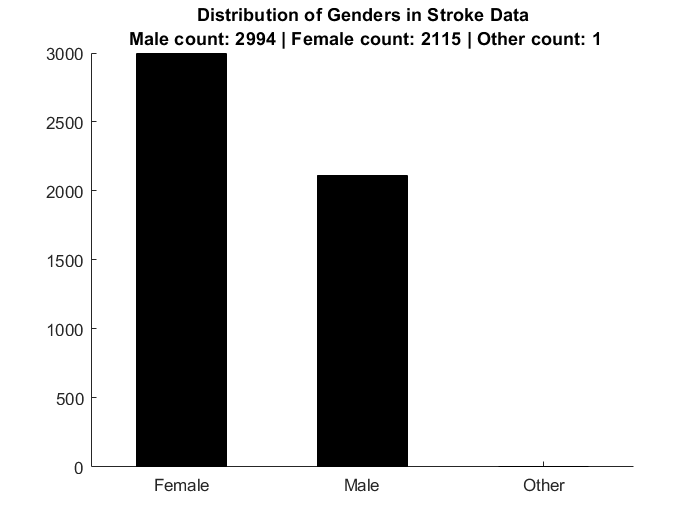

gender_dist_plot = figure(1);
clf(gender_dist_plot) %note: this just clears the figure so changes can be made and the old ones will disappear.
hold on
% grabbing the plotting values
gender_dist = histcounts(categorical(gender_array),sort_gender_categories);
%plotting the information
bar(sort_gender_categories,gender_dist,0.5,'k');
%interesting title for the plot
gender_plot_title = sprintf("Distribution of Genders in Stroke Data\n Male count: %d | Female count: %d | Other count: %d",...
                            gender_dist(1),gender_dist(2),gender_dist(3));
title(gender_plot_title);
hold off

#### Second, basic statistics about age. Let's do some binning and look at the distribution.

%grabbing the age data
age_array = strokedata.age;

%Going to do a subplot
% Subplot 1: All ages ... no binning
% Subplot 2: All ages ... binned within a range
%   (ex. bins of 5 years, 21-25 | 26-30 | 31-35 etc.)

age_distribution_plot = figure(2);
clf(age_distribution_plot)

hold on
subplot(1,2,1);
% PLOT 1 Script 
no_bins_edges = [0.5:1:99.5]; %Should indicate to "histogram" function what values we want in these bins.
age_no_bins_hist = histogram(age_array,no_bins_edges,'FaceColor',[0.3, .6, 0.3]);
%Modifying histogram
titleforsubplot1 = sprintf("Distribution of ages without bins\n(each integer age plotted separately)");
title(titleforsubplot1);
xlabel("Ages");

%PLOT 2 Script
subplot(1,2,2);
%going to use features of "historgram" function to do binning
age_bins_hist = histogram(age_array,'BinMethod','auto') %didn't suppress so we can see the properties of this plot

age_bins_hist =   Histogram with properties:

             Data: [5110×1 double]
           Values: [255 217 227 267 270 279 330 325 363 367 431 403 349 272 237 332 186]
          NumBins: 17
         BinEdges: [0 5 10 15 20 25 30 35 40 45 50 55 60 65 70 75 80 85]
         BinWidth: 5
        BinLimits: [0 85]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


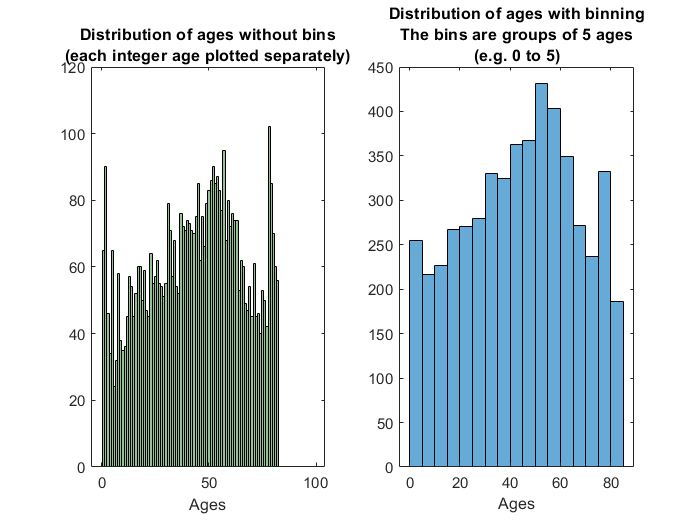


titleforsubplot2 = sprintf("Distribution of ages with binning\nThe bins are groups of %d ages\n(e.g. %d to %d)",...
                             (age_bins_hist.BinEdges(2)-age_bins_hist.BinEdges(1)),...
                              age_bins_hist.BinEdges(1), age_bins_hist.BinEdges(2));
title(titleforsubplot2)
xlabel("Ages")

hold off

The age distributions reveal some deviations from a normal data distrbitution. Age does not seem like a feature that would generally follow a normal distribution, but it's still important to keep of the trends in this data among the subjects.

In particular, it is interesting that the distribution of all ages has large spikes at very high and very low ages. The age 1 bin has nearly 100 subjects from the study. The study was conducted among patients in a hospital, so seeing 100 babies in a hospital is not unexpected since they likely make far more visits to doctors than the average healthy adult, but this group may need to be separated out when it comes to using this data for predicting strokes. **It is unlikely that babies and young children can effectively provide information about predicting the potential for a stroke.**

*Just wanted to throw a comment in here that the bolded line above is some of the stuff we should be looking to extract and talk about in EDA (exploratory data analysis). We very likely will have to filter out a group of ages, although there might be a more convenient way to do this then selecting an arbitrary age. For example, I'll bet the younger parts of the distribution have N/A for "work_type" so we can remove subjects below 40 and don't work or something. -- P Dunn*